linearModel



%second cycle
i = 1;
x = 0
for i = 1:25
    x = 0 + simRes.x{i,1}(end,:)
end
x = x/25        




% Parameters --------------------------------------------------------------

params.tFinal = 2;
params.R0 = zonotope([x',0.1*diag(ones(5,1))]);
%params.R0 = bb;
params.U = zonotope(interval([0.9; -0.25; -0.1; 0.25; -0.75], ...
                             [1.1; 0.25; 0.1; 0.75; -0.25]));


% Reachability Settings ---------------------------------------------------

options.timeStep = 0.02; 
options.taylorTerms = 4;
options.zonotopeOrder = 20; 


% System Dynamics ---------------------------------------------------------

A = [-1 -4 0 0 0; 4 -1 0 0 0; 0 0 -3 1 0; 0 0 -1 -3 0; 0 0 0 0 -2];
B = 1;

fiveDimSys = linearSys('fiveDimSys',A,B);


% Reachability Analysis ---------------------------------------------------

tic
R = reach(fiveDimSys, params, options);
tComp = toc;

disp(['computation time of reachable set: ',num2str(tComp)]);


% Simulation --------------------------------------------------------------

simOpt.points = 25;
simOpt.type = 'gaussian';

simRes = simulateRandom(fiveDimSys, params, simOpt);


% Visualization -----------------------------------------------------------

% plot different projections
dims = {[1 2],[3 4]};

for k = 1:length(dims)

    figure; hold on; box on
    useCORAcolors("CORA:contDynamics")
    projDims = dims{k};

    % plot reachable sets
    plot(R,projDims, 'DisplayName', 'Reachable set');

    % plot initial set
    plot(R.R0,projDims,'DisplayName','Initial set');

    % plot simulation results
    plot(simRes,projDims, 'DisplayName', 'Simulations');

    % label plot
    xlabel(['x_{',num2str(projDims(1)),'}']);
    ylabel(['x_{',num2str(projDims(2)),'}']);
    legend('Location', 'northwest')
end

% example completed
res = true;

[f,h]=nonLinear_Gsp();
% x0=[1 15 70];
x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)
input = interval([0; 0; 0;],[400; 4; 400])
dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end



[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)
input = interval([0; 0; 0;],[400; 4; 400])
dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u1，u2 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)
input = interval([0; 0; 0;],[0; 0; 400])
dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u2，u3 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)
input = interval([0; 0; 0;],[400; 0; 0])
dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u1，u3 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)
input = interval([1; 0; 0;],[1; 4; 0])
dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    [x_out, set] = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    R_zonotope_set = set.timePoint.set
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

n = max(size(r1))
for i = 1: n
    a1 = r1(i)
    a2 = r2(i)
    a1_zono = a1{1,1}
    a2_zono = a2{1,1}
    res(i) = a1_zono & a2_zono
end

S1 = interval([-1;-1],[2;2])
S2 = interval([-2;-2],[1;1])
res = S1 & S2

zonobundles example but not working

Z{1} = zonotope([1 1 1; 1 -1 1]); % create zonotope Z1;
Z{2} = zonotope([-1 1 0; 1 0 1]); % create zonotope Z2;
Zb = zonoBundle(Z); % instantiate zonotope bundle from Z1, Z2
% vol = volume(Zb) % compute and display volume of zonotope bundle

figure; hold on
plot(Z{1}); % plot Z1
plot(Z{2}); % plot Z2
hold off
figure;
plot(Zb); % plot Zb in gray

% zonotope bundles are closed under intersections, but Minkowski addition
% is no longer exact
%% Example 1
% % convert to polytopes
% Pb = polytope(Zb)
% P1 = polytope(Z{1})
% 
% % compute exact Minkowski addition
% Pres = Pb + P1
% 
% % compute over-approximate addition
% Zres = Zb + Z{1}
% 
% % compare results
% figure; hold on
% plot(Pres); % plot Pres
% plotFilled(Zres,[1 2],[.675 .675 .675],'EdgeColor','none'); % plot Zres
% 
% %% Example 2
% % generate new zonotopes
% Z{1} = zonotope([0 0.5 1 2; 0 0.5 2 1]);
% Z{2} = zonotope([0 3 -0.7; 0 3 0.7]);
% 
% Zadd = zonotope([0 2 0; 0 0 1]); % create zonotope to be added;
% Padd = polytope(Zadd); % convert zonotope to polytope
% 
% Zbundle = zonotopeBundle(Z); % create zonotope bundle
% Pmpt = polytope(Zbundle); % convert zonotope to polytope
% 
% P_final = Pmpt + Padd; % compute exact Minkowski addition for polytopes
% Zbundle_final = Zbundle + Zadd; % compute overapprox. Minkowski addition
% 
% %plot results
% figure; hold on
% plot(Zbundle_final); % plot Zbundle_final
% plotFilled(P_final,[1 2],[.675 .675 .675],'EdgeColor','none');% plot P_final

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
[A,B,C,D]=linear_Gsp(f,h,x0);
input = input_initial();
dims = {[1 2],[1 3]};
s = tic
parfor redun_situation = 1:7
    x0=[1 15 70];
    timestep = 2;
%     for k =1:1
        [x_out, set] = reach_analysis_lin_dis(timestep,A,B,dims,x0,input{redun_situation})
        x0 = x_out;
        R_zonotope_set{redun_situation} = set.timePoint.set;
%         [A,B,C,D]=linear_Gsp(f,h,x0)
%     end
end
totalt = toc(s);
disp(totalt)

try to get intersection from the sets

t_intersection = tic

t_intersection = uint64
650513197099

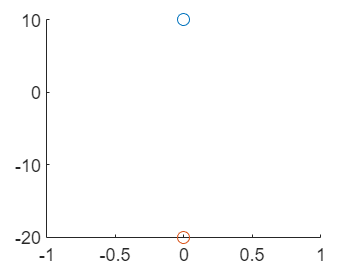

Index in position 2 exceeds array bounds.

Error in zonoBundle/plot (line 112)
    inTol = all(withinTol(V(:,1),V,eps), "all");


ZB = {};
figure();

for kk = 1:11 % 11 stands for eleven timepoints in the 2s simulation time
    A = {};
    for i = 1:2
        
        colum = R{i}.timePoint.set;
        
        A{i} = colum{kk,1};
    end
    ZB{kk} = zonoBundle(A);
%     grap(kk) = figure(); hold on;
    for j = 1:length(dims)
        projDims = dims{j};
        plot(ZB{kk},projDims);
        hold on;
    end
%     projDims = [1,2,3];
%     plot(ZB{kk},projDims);
%     hold on;
end

toc(t_intersection)

dims = {[1 2],[1 3]};
sys = system_def();
Result = constant_redundancy_lin(sys);



figure(1);
projDims = dims{1};
    for i = 1:max(size(Result))
        plot(Result{i},projDims);
        hold on;
    end
    hold off;        


 for kk = 1:max(size(R{1,1}.timePoint.time)) % kk stands for num of timepoints
        
     
         A(kk,:) = zonoBundle({R{1}.timePoint.set{kk,1},R{2}.timePoint.set{kk,1}});

%         for j = 1:length(dims)
%             projDims = dims{j};
%             plot(AAA,projDims);
%             hold on;
%         end
 end


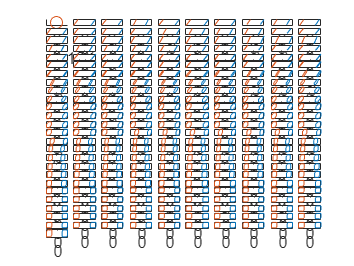

 
 figure();
 
 for kk = 1:max(size(R{1,1}.timePoint.time))
     subplot(26,10,kk);
     plot(Result{1}.timePoint.set{kk,1},[1,2]);
     hold on;
     plot(Result{2}.timePoint.set{kk,1},[1,2]);
     hold off;
 end